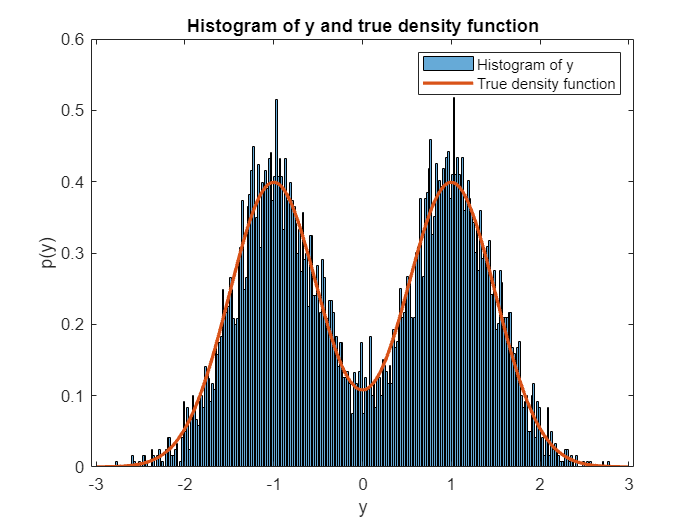

%MMSE and MAP estimators
clear
clc
% Define parameters
sigma2 = 0.5^2;
theta = [-1 1];
prior = [0.5 0.5];

% Simulate noisy observation of theta
n = 3*1e3; % number of simulations
theta_idx = randi([1 2], n, 1);
theta_sim = theta(theta_idx);
w_sim = sqrt(sigma2) * randn(n, 1);
y_sim = theta_sim + w_sim;

% Plot histogram of y
histogram(y_sim, 'Normalization', 'pdf')
hold on

% Plot true density function of y
x = -3:0.01:3;
p_y = prior(1)*normpdf(x, -1, sqrt(sigma2)) + prior(2)*normpdf(x, 1, sqrt(sigma2));
plot(x, p_y, 'LineWidth', 2)

% Add labels and legend
xlabel('y')
ylabel('p(y)')
title('Histogram of y and true density function')
legend('Histogram of y', 'True density function')



%bc
f = @(y) 0.5*1/sqrt(2*pi*sigma2)*exp(-(y-1)^2/(2*sigma2))+0.5*1/sqrt(2*pi*sigma2)*exp(-(y+1)^2/(2*sigma2));
f(0.7)

q = @(theta,y) 1/sqrt(2*pi*sigma2)*exp(-(y-theta)^2/(2*sigma2));
q(1,0.7)